# 1.4 Homework 3

*Simulation and control of the pitch angle dynamics of a JAS 39 Gripen is discussed in this homework, but first we give some background. The dynamics of an airplane is highly nonlinear. The control system is based on gain scheduling of speed and altitude to compensate for some of the nonlinearities. For the JAS 39 Gripen, linear models have been obtained for approximately 50 different operating conditions. The models are the result of extensive research including wind tunnel experiments. A linear controller is designed for each linear model, and a switching mechanism is used to switch between the different controllers. Many of the parameters in the models vary considerably within normal operation of the aircraft. Two extreme cases are “heavily loaded aircraft at low speed” and “unloaded aircraft at high speed”. The case when the velocity of the aircraft is approximately equal to the speed of sound is also critical, because at higher velocities the aircraft is stable while for lower it is unstable. The velocity of an aircraft is specified by the Mach number *$M = v/a$*, which is the conventional velocity v normalized by the speed of sound a. The following sketch of the JAS 39 Gripen illustrate the state variables of the system:*

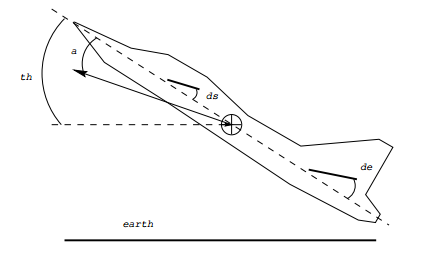

*The direction in which the aircraft is pointing defines the pitch angle *$θ$*. The pitch angle does not necessarily equal the angle of the velocity direction of the aircraft (indicated by an arrow from the center of mass). The difference is the angle of attack *$α$*. JAS 39 Gripen has two surfaces for controlling the pitch angle: the spoiler and the elevator. Their corresponding angles are denoted *$δ_s$* and *$δ_e$*, respectively. The state-space model considered in the homework consists of the seven states*

                                                                            $\alpha$*             Angle of attack*

                                                                            $q = \dot{\theta}$*        Pitch rate*

                                                                            $\theta$*              Pitch angle*

                                                                            $\partial_e$*            Elevator angle*

                                                                            $\partial_s$*            Spoiler angle*

                                                                            $x_e$*            Internal elevator angle*

                                                                            $x_s$*            Internal  spiler angle*

*where the latter two states correspond to dynamics in the rudder servos. The control inputs are*

                                                                            $u_e$*        Elevator command*

                                                                            $u_s$*        Spoiler command *

*We consider a linear state-space model for normal load at *$M = 0,6$* and altitude 1 km. This model has been released by SAAB Military Aircraft and discussed in a master thesis at Chalmers [1]. The model is given by*


$$\dot{x} =Ax+Bu,$$


*where *

$x = (\alpha, q, \theta, \partial_e, \partial_s, x_e, x_s)^T$*, *$u = (u_e, u_s)^T$*.*

*Download the Matlab files from the course homepage to your current directory and introduce the state-spacemodel into the Matlab workspace by running*

>> jasdata

***1. [1p] ****Which are the dynamical modes of the JAS 39 Gripen state-space model, i.e., which are the eigenvaluesof A? Is the model stable? Which eigenvalues correspond to the flight dynamics and which correspond to the rudder dynamics?*

The eigenvalues of the system is obtained by:


$$det\left(\lambda −AI\right)=0$$


running:

>> A
A =   -1.3936    0.9744   -0.0019   -0.5349   -0.0071   -1.0562    0.4891
       5.6870   -1.1827    0.0002  -25.9398    7.9642  -23.8594   -6.2531
           0    1.0000         0         0         0         0         0
           0         0         0  -20.0000         0 -312.5000         0
           0         0         0         0  -20.0000         0 -312.5000
           0         0         0         0         0 -125.0000         0
           0         0         0         0         0         0 -125.0000
     
>> eig(A)

ans =

   -3.6452
    1.0662
    0.0027
  -20.0000
  -20.0000
 -125.0000
 -125.0000

Some eigenvalues $\lambda_2 =1\ldotp 0662$ and $\lambda_3 =0\ldotp 0027$ are greater than zero and placed on RHP which indicates the unstability of the system.  It's due to the fact that the flight dynamics are unstable. The fast dynamics of internal elevator state and internal spoiler state should be expected since they are related to the dynamics . Same thing applies to  rudder servos and spoiler angle. 

Values of $\lambda_4 ,\lambda_5 ,\lambda_{6\text{ }}$has larger magnitude, In fact they should correspond to the rudder dynamics and naturally $\lambda_1 ,\lambda_2 ,\lambda_3$ should correspond to flight dynamics.  It's natural to assum that the rudder dynamics are not dependent to flight dynamics.  as seen in the matrix the $\delta_e$, $\delta_s$, $x_e$, $x_s$ has dynamics that are not dependend on $\alpha$, $\theta$, $\dot{\theta}$. That can also be shown by the fact that:


$$eig(A) = eig(A_r) \cup eig(A_f)$$


If we take $A_r$ as:


$$A_r = \pmatrix{ −1.3936 &0.9744 & −0.0019 \cr 5.6870 & −1.1827 & 0.0002 \cr 0 &1.0000 & 0}$$


and $A_f$:


$$	A_f = \pmatrix{ 20.0000   &   0 &	     -312.50     & 0 \cr
           0  & -20.0000   &      0& -312.50 \cr
           0   &      0 &-125.0000  &      0 \cr
           0    &     0  &       0 & -125.0000}$$


The eigen values of these shows that the flight dynamics are unstable.

**2. [1p]** Choose a nominal design for the state feedback by typing

>> design1

*Look at the L-matrix. Which states are used in the feedback loop? Which are the eigenvalues of A−BL? Why is there an eigenvalue close to the origin?*

>> L

L =

    0.1585    0.0668         0   -0.0863    0.0251         0         0
   -0.2060   -0.0871         0    0.1120   -0.0339         0         0

The state involved in the L-Matrix are $\alpha, \dot{\theta},  \partial_e, \partial_s$. The pilot acts on $x_e, x_s$ which impacts on $\delta_e$, $\delta_s$ and has a huge effect on $\theta$. 

The eigenvalues of of  $det( \lambda I-(A-BL)) = 0$ are

-3.57
-1.3165
-0.0002
-20.0084
-20.0286
-122.6750
-124.9776

The flight dynamics are stablized now. The eigen value $\lambda_3$ is close to zero and represents the pitch dynamics.  If now we calculate the eigen vector of $\lambda_3$ we get following vector:


$$v_{\lambda_3} = \pmatrix{0.0015\cr 0.0002 \cr -1 \cr 0.0002 \cr -0.0003 \cr 0 \cr 0}$$


As seen $\lambda_3$ has a huge impact on pitch angle. The reason why it is close to the origin require an understanding about how the aeroplane is acting. it would be abnormal to have a fast dynamics on pitch angle becouse of the weight and size of the aerplance. And that eigen value is not meant to be stabilized by the feedback. That is instead left to the pilot. On the other hand the impact of the feedback is on $\lambda_2$ which is corresponted to the pitch rate. 

*The pilot may be modeled as a PD-controller with a time delay of 0:3 s. Argue why this is a reasonable model. Let*


$$u_{pilot} =K_p \frac{1+T_d s}{1+\frac{T_d }{N}s}e^{−0\ldotp 3s} \left(\theta_{ref} −\theta \right)$$


*where θref corresponds to the desired pitch angle. Set Kp = 0:2, Td = 0:5, and N = 10. Simulate the closed-loop system including the pilot. Check the magnitudes of the rudder angles (plot(t,x(:,[4 5]))). Why is it important that the rudder angles are not too large?*

The choice of PD as controller and as pilot is given with a delay.

- The delay is reasonable due to reaction response from the pilot. 

- The proportional part is reasonable since a pilot or human being reacts more the error and gives commands proportional to the error. 

- The derivation is reasonable since it represents the rate of the error. It's mainly interperted as "what will happen in the future?" by the pilot. If the error continues the pilot may get paniced and lead to more error which is represented by the derivation part.

- The integration part is not involved in this model since the pilot will not care about what happened before in normal condition. He will only think about what will possibly happen in future and now.

The plot of the rudder angles is:

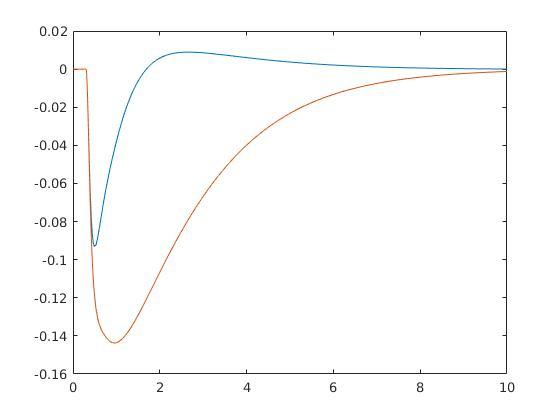

The rudder angles should not be so high is order to  avoid saturated behaviour and overuse of actuators. Rudder angles effect the pitch rate which in turn has effect on pitch angles and angle of attack.  The pitch rate effects both angle of attack and pitch angle in the same way since we have $A_{12} \approx 1$ and $A_{32} = 1$. 

***3. [1p]**** In order to analyze the PIO mode, we will replace the PD-controller pilot by a relay model. The pilot then gives maximal joystick commands based on the sign of θ. Such a “relay pilot” can be found in the Simulink pilot model library; run*

>> pilotlib

*Plot the Nyquist curve of the linear system from upilot to θ. This can be done by deleting the feedback path from θ, connecting an input and an output at appropriate places (inputs and outputs are found in the simulink libraries), saving the system to a new file and using the linmod and nyquist commands. Change pilot in the plane model by deleting the PD-controller pilot and inserting the “relay pilot”. The describing function for a relay is*


$$N\left(A\right)=\frac{4D}{\pi A}$$
    

*What is D for the “relay pilot”? Use describing function analysis to predict amplitude and frequency of a possible limit cycle. Simulate the system. How good is the prediction?*

*Suppose that the error is *$e(t)= \theta_{ref}-\theta$ and is the input to the nonlinearity of the system. Suppose further that the amplitude of the error is $A$ and the frequency is $\omega$. We consider $u(t)$ is the output of the nonlinearity and the nonlinearity is low pass filter such that $|G(jn\omega)| \ll |G(j\omega)|$ for $n \geq 2$. The describing function model on the nonlinearity is :


$$N(A,\omega) = \frac{b_1(\omega)+ja_1(\omega)}{A}$$


$b_1$ and $a_1$ are those firs coefficient of the fourier transform of $u(t)$.  Now the maximum amplitude of this oascillation is given by:


$$max|y(t)| \approx |G(j \omega) | \sqrt{a_1^2 + b_1^2} = | G(j \omega) ||N(A,\omega) | A$$


The decribing function is given according to :


$$N(A) = \frac{4D}{\pi A}$$


$A$ is the amplitude of the oscillation and $D$ is the output value and is 0.2. The idea is to chech sustained oscillation with a certain frequency $\omega$.  For the open loop system with a gain $1$ and phase -$\pi$ with that frequency we have:


$$G(j\omega) N(A) =-1 \rightarrow G(j\omega)=\frac{-1}{N(A)}$$


The maximum amplitude as describe earlier:


$$max| y(t) | \approx |G(j\omega) | | N(A,\omega) |A = A$$


The describing function does not contribution to phase is this case then we look  for the $\omega$. In order to do so we look at the linearized system's Bode & Nyquist diagram.  By investigating the Bode and Nyquist we see that  $argG(j\omega) = -\pi$ is fulfilled for $\omega \approx 2.77$. The Nyquist show the real part at $-0.402$ and imaginary part at $0.00172$ or $\approx 0$.  Using prevoiuse formulas we get 


$$G(j2.77) = -0.402 = -\frac{\pi A}{4D} \rightarrow A \approx 0.1024$$


The period of the pscillation is then $\frac{2\pi}{\omega} =2.27 s$. According to the simulated system the oscillation is around 1 rad with - + 0.1 rad which is  almost 2.34. That is close to the calculations.  The Describing function method gave a good estimation. we get a good approximation when looking at the frequency as well.

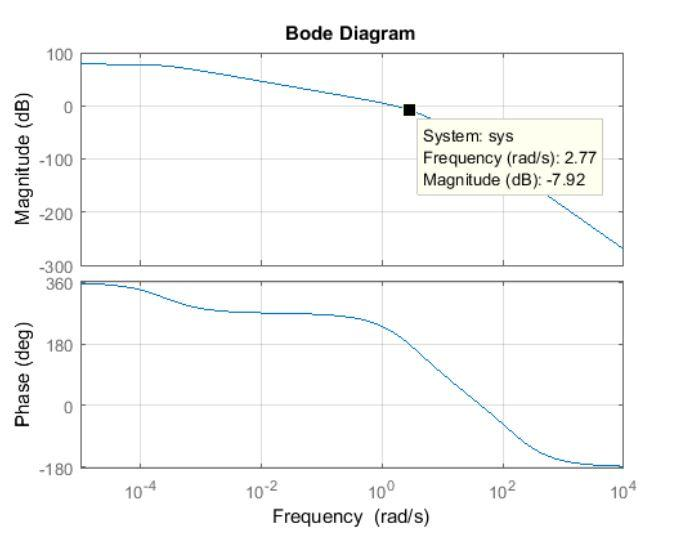

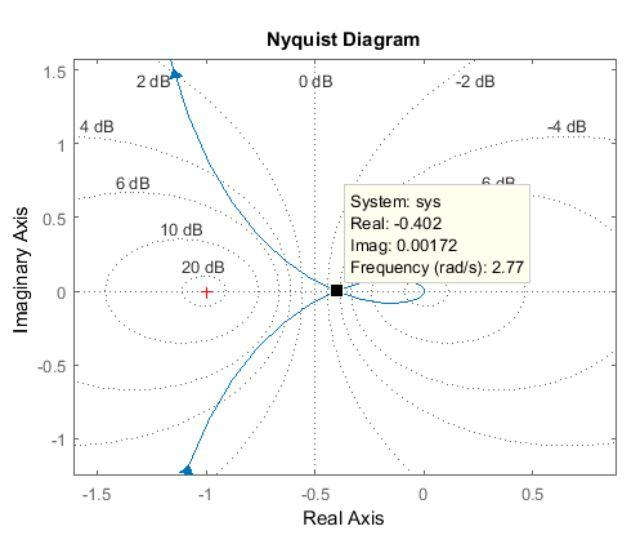

***4.[1p] ****Use ****design2**** to change *$L$* and *$K_f$* to a faster design. Is the PIO amplitude decreased? Make the pilot filter faster by reducing the filter time constant to *$T_f = 0,03 $* (****Design3****) Is the PIO amplitude decreased? Discuss the results using the describing function method and thus plot the Nyquist curves from *$u_{pilot}$* to *$θ$*. Are there any drawbacks with the design that gives smallest PIO amplitude?*

*From now on let's remember*


$$arg(G(j \omega) ) = -\pi \: \:\:\:\:\: \:\:\:\:(1)$$


Starting with Design 2 following Bode and Nyquist plots are presented.

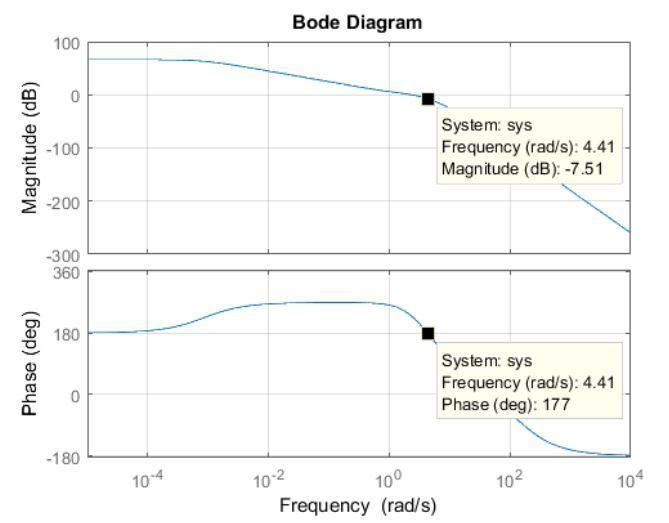

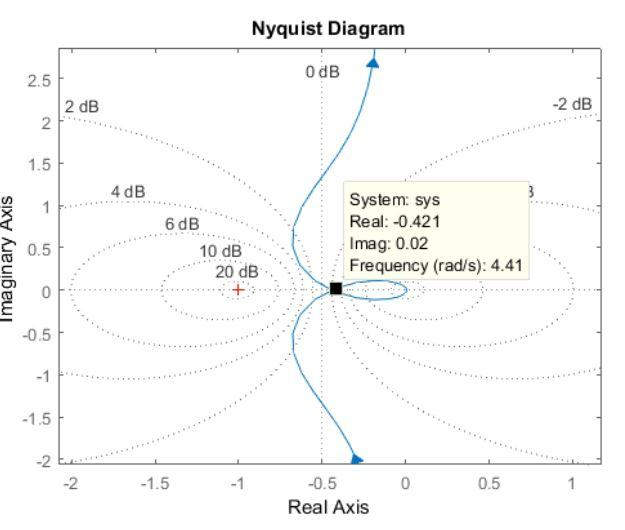 

From condition(1) we get that the condition is fulfilled for $\omega \approx 4.4$. The real part in Nyquist is $-0.421$ and the imaginary part is near $0$.  Same procedure in task 3 gives 


$$A \approx 0.1073$$


The period is then $1.428$.

In design 3. Following Nyquist and Bode are obtained.

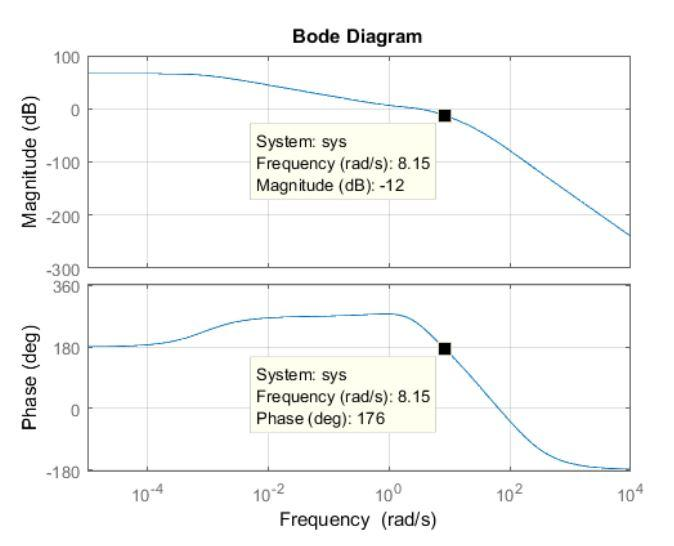

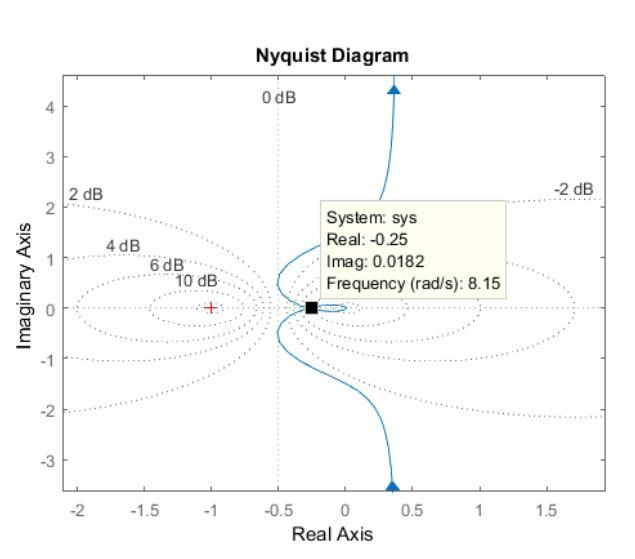

Following condition (1) and the prodecure in task 3 we get $\omega \approx 8.15$. The real part for this frequency in Nyquist is $-0.25$ and an imaginary part close to $0$. The amplitude is 


$$A \approx 0.0637$$


And the period $0.771$ s. 

We use following graph to make a observation

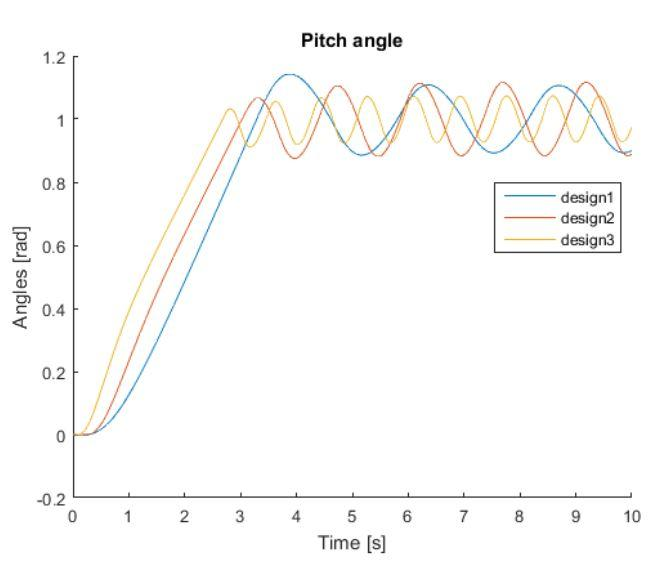

Following observations are made:

- The simulated result and those obtained by theory are very close to each other.  notice the amplitude 0.106 and 0.071 and period 1.48 and 0.88 s for design2 and design 3. 

- Comparision of design 2 with design 1 we see that the amplitude is almost the same while the period is smaller in design 2. The system is now faster but the pilot commands slower. This leads to the fact that the oscillation occure more frequently

- Looking at the design 3 , we see that the amplitude and the period is decreased in comparision to design1. The pilot command are faster. The low pas filter will then get the the reaction pilot faster. 

***5.[1p]**** Suggest a control strategy for reducing PIO in JAS 39 Gripen, with minimal influence on the pilots ability to manually control the plane. Analyze the performance of your strategy and compare it to the previous two designs. It should outperform the previous ones.*

To improve the behaviur of the system a new design is presented. This design is based design 1 and design 3. The constant time factor is used from design 3. We make the same procedure as in task 3. following graphs are obtained

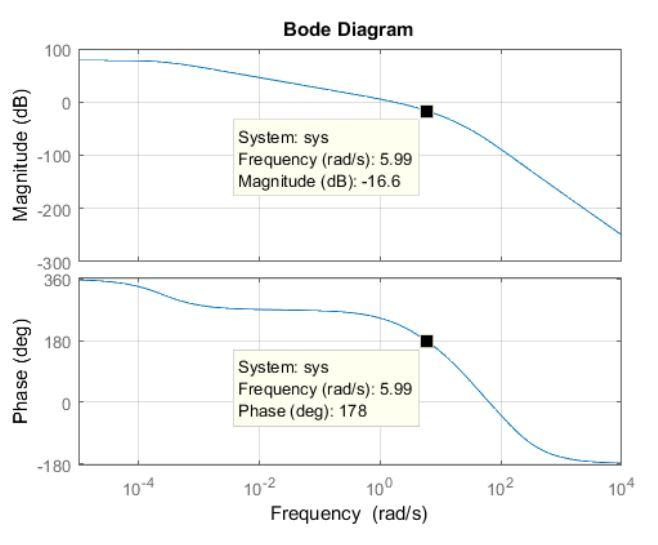

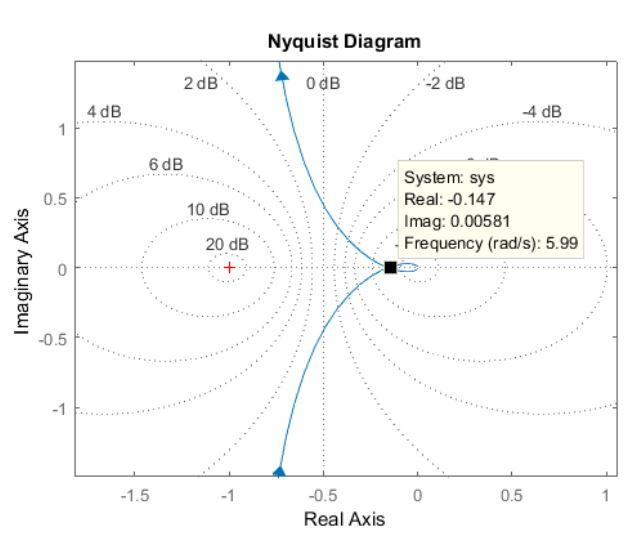

Using condition (1) we see that $\omega = 5.99$. Nyquist gives a real part of 0.147 and imaginary part close to 0. so we get 


$$G(j5.99) \approx -0.147  = - \frac{\pi A}{4D} \rightarrow A \approx 0.0374$$


Same method to plot the Pitch angle is given below

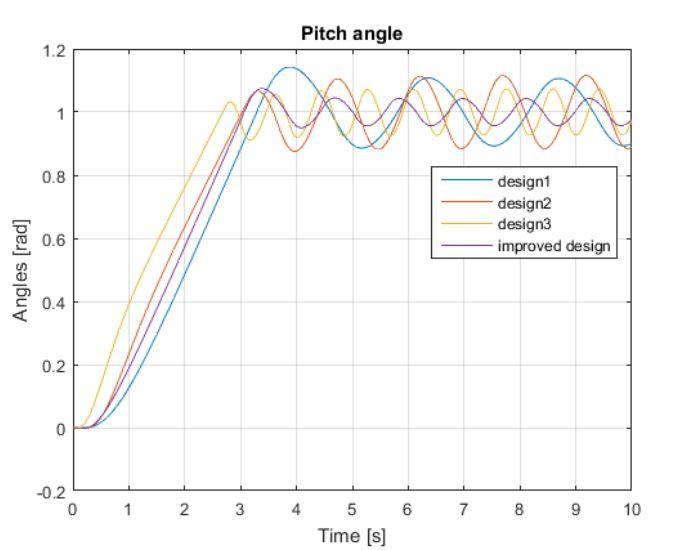

The simulated amplitude is 0.043 and the period is 1.128s . If we compare all the designs we see that the improved design gives smallest amplitude. The system is slower and the pilot command is faster. . The period is smaller than Design 3 but bigger than design 1.  The period is big which means that the pilot will not make faste movements and commands.